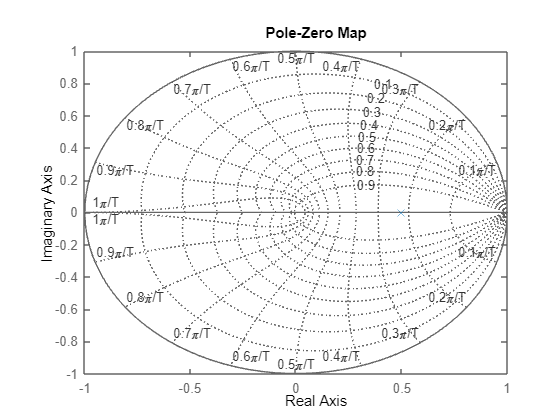

%%%%% 1.1
% Define the system transfer function
R0 = 0.5; 
numerator = 1;
denominator = [1, -R0];

% Create a system object
sys = tf(numerator, denominator, 1);

% Plot the pole-zero plot
pzmap(sys);
grid on

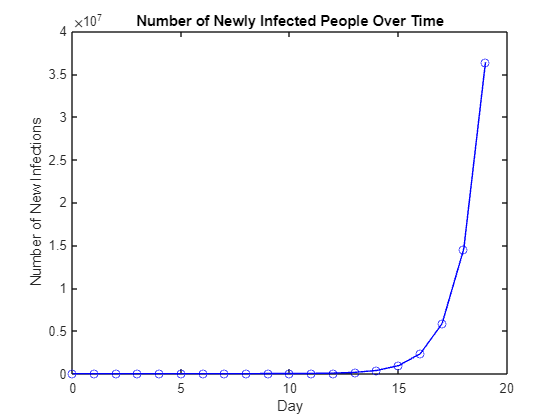

%%%%% 1.2
% Parameters
R0 = 2.5; % Change this value as needed
n = 20;  % Number of days

% Initialize an array to store the number of newly infected people
new_infections = zeros(1, n);

% Initial condition (one infected person on day 0)
new_infections(1) = 1;

% Calculate the number of newly infected people for each day
for day = 2:n
    new_infections(day) = R0 * new_infections(day - 1);
end

% Plot the number of newly infected people over time
figure;
plot(0:n-1, new_infections, 'b-o');
title('Number of Newly Infected People Over Time');
xlabel('Day');
ylabel('Number of New Infections');


% Display the final number of newly infected people
final_infections = new_infections(end);
fprintf('Number of newly infected people after %d days: %d\n', n, final_infections);

Number of newly infected people after 20 days: 3.637979e+07


%%%% 1.3
% Parameters
R0 = 2.5;
target_infections = 1e6; % 1 million

% Initialize the number of newly infected people and day counter
new_infections = 1; % Initial condition
n = 0;

% Calculate the number of days required to reach the target infections
while new_infections < target_infections
    n = n + 1;
    new_infections = R0 * new_infections;
end

fprintf('It will take %d days to reach 1 million new daily infections with R0 = %.1f.\n', n, R0);

It will take 16 days to reach 1 million new daily infections with R0 = 2.5.


%%%%%% 1.4
% Given covid_cases array
covid_cases = [40709, 40646, 40593, 40641, 40242, 39831, 39175];

% Initialize an array to store the results of division
division_results = zeros(1, length(covid_cases) - 1);

% Calculate the division results and store them
for i = 2:length(covid_cases)
    division_results(i - 1) = covid_cases(i) / covid_cases(i - 1);
end

% Calculate the average of the division results
average_result = mean(division_results);

% Display the division results and the average
disp('Division results:');

Division results:


disp(division_results);

    0.9985    0.9987    1.0012    0.9902    0.9898    0.9835



disp(['Average of division results: ', num2str(average_result)]);

Average of division results: 0.99364


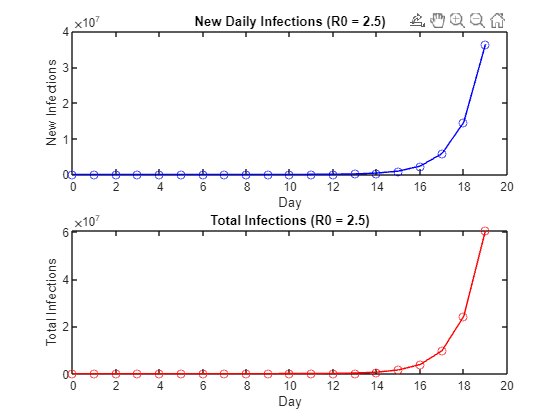

%%%%%%%%%% 1.5
% Parameters
R0 = 2.5;
n = 20;  % Number of days

% Initialize arrays to store new daily infections and total infections
new_infections = zeros(1, n);
total_infections = zeros(1, n);

% Initial infection (one infected person on day 0)
new_infections(1) = 1;
total_infections(1) = new_infections(1);

% Calculate new daily infections and total infections
for day = 2:n
    new_infections(day) = R0 * new_infections(day - 1);
    total_infections(day) = total_infections(day - 1) + new_infections(day);
end

% Plot new daily infections
figure;
subplot(2, 1, 1);
plot(0:n-1, new_infections, 'b-o');
title('New Daily Infections (R0 = 2.5)');
xlabel('Day');
ylabel('New Infections');

% Plot total infections
subplot(2, 1, 2);
plot(0:n-1, total_infections, 'r-o');
title('Total Infections (R0 = 2.5)');
xlabel('Day');
ylabel('Total Infections');


% Display the final total infections
final_total_infections = total_infections(end);
fprintf('Total infections after %d days: %d\n', n, final_total_infections);

Total infections after 20 days: 6.063298e+07
